**Read Image**

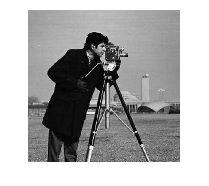

[Im_ori,map] = imread('Cameraman.png');
Im_ori= ind2gray(Im_ori,map);


imshow(Im_ori)

**4.2 Implementation of adding Gaussian noise**

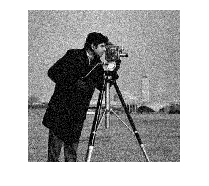

NoiseLevel = 20;
sigma = (NoiseLevel*NoiseLevel)/(255 * 255);
Im_noisy = imnoise(Im_ori, 'gaussian', 0, sigma);
Im_noisy = im2double(Im_noisy);
imshow(Im_noisy);

**For a given vectorized image x∈Rd (d = m * n), let X = mat(x) :**

In this case,literally nothing we can do, X is just Im_noisy or v.

[m, n] = size(Im_noisy);
d = m*n;
v = reshape(Im_noisy, [], 1);
X = im2double(reshape(v, [m, n]) );


lambda = 0.2;% initial λ 0.2
mu = 0.1; % initial µ 0.1
K = 10;

I2d_lambda_BBT = cal_I2d_lambda_BBT(m,n,lambda);

prox_phi = @(x, mu) max(abs(x) - mu, 0).*sign(x); %proximity算子
Bx0 = cal_Bx_by_x(X,m,n);
Bx = Bx0;
Y = Bx0;

% Fixed-point proximity algorithm
for k = 1:K
    % 先计算更新的 Bx + (I2d − λBBT) * y[k−1]
%     tBTY = cal_Bty_by_y(Y,m,n); % 计算 B' * y
%     tu = double(v) - lambda*tBTY; % 更新u
%     tX = reshape(tu, [m, n]);  % 更新 X
%     Bx = cal_Bx_by_x(tX,m,n); % 更新Bx/Bu/Bv
    factor = Bx + I2d_lambda_BBT * Y; 

    Y = factor - prox_phi(factor, mu/lambda); % Apply the proximity operator here

end

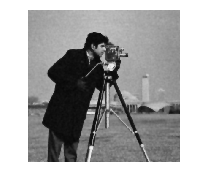

[BTY] = cal_Bty_by_y(Y,m,n);
u = double(v) - lambda*BTY;
finalPic = reshape(u, [m, n]);  
imshow(finalPic);

diff = (finalPic-Im_noisy);
